# Analyze the Data 

In this livescript, we perform some analysis on the experiment of examining eyes open vs. eyes closed. As a reminder, we visualized this data previously in the first livescript. However, as a brief refresher, let's take a look at a subsection of a dataset again. 

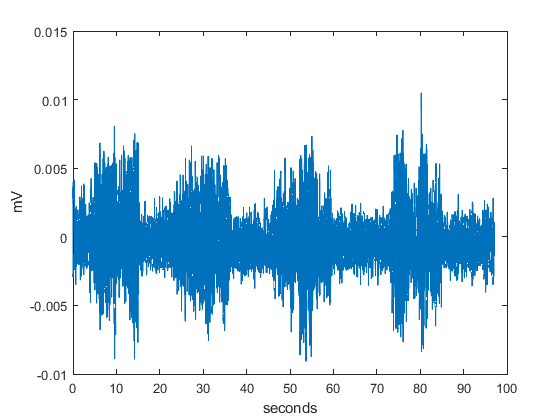

plot(t,EEGsignalRaw)
xlabel('seconds')
ylabel('mV')

We can see that there is a visible difference in the shape of the signal when we switch from eyes open to eyes closed, with the eyes closed portion of the data showcasing those alpha waves (the 4 sections of the signal that are higher in magnitude). However, we can also use some additional computational tools to make this much more clear. 

Several of the following steps rely on a technique called the Fourier transform. While we won't go too much into the math, the MathWorks documentation page has a quick explanation [here](https://www.mathworks.com/help/matlab/math/fourier-transforms.html). The following is an excerpt from that page: "The Fourier transform is a mathematical formula that relates a signal sampled in time or space to the same signal sampled in frequency. In signal processing, the Fourier transform can reveal important characteristics of a signal, namely, its frequency components."

We use the Fourier transform in situations where analyzing the signal data in its' original domain is challenging. In our case, the EEG data we have currently is time vs. mV. However, with the Fourier transform we can instead look at this data in the frequency domain, which makes it extremely useful when trying to correlate alpha waves (which appear only at a certain frequency) to either eyes open or eyes closed. Here is a quick illustration (adapted from the documentation [here](https://www.mathworks.com/help/matlab/math/fourier-transforms.html)):

Let's see the plot of the following 15 HZ signal (created using the sin function):

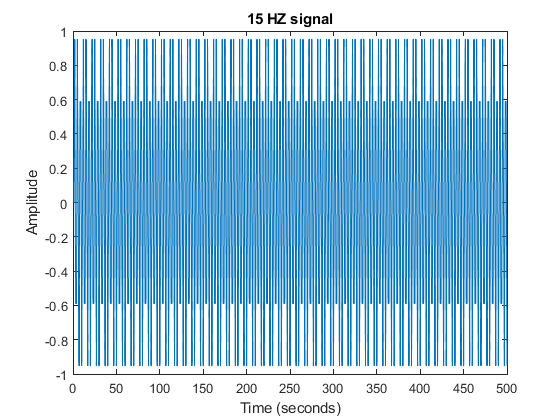

Ts = 1/50;
t2 = 0:Ts:10-Ts;  
plot(sin(2*pi*15*t2))
title('15 HZ signal')
xlabel('Time (seconds)')
ylabel('Amplitude')

Now let's plot another signal, but this time a 20 HZ one:

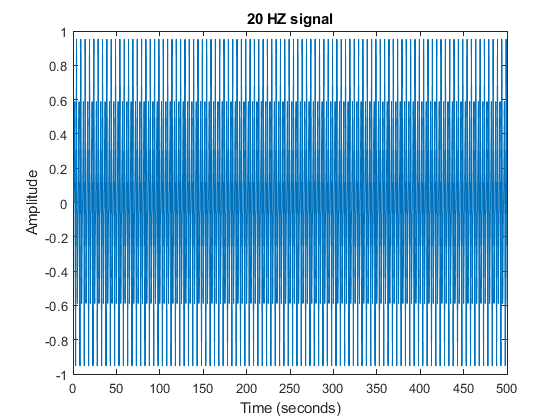

plot(sin(2*pi*20*t2))
title('20 HZ signal')
xlabel('Time (seconds)')
ylabel('Amplitude')

Now let's try plotting the two signals when added together:

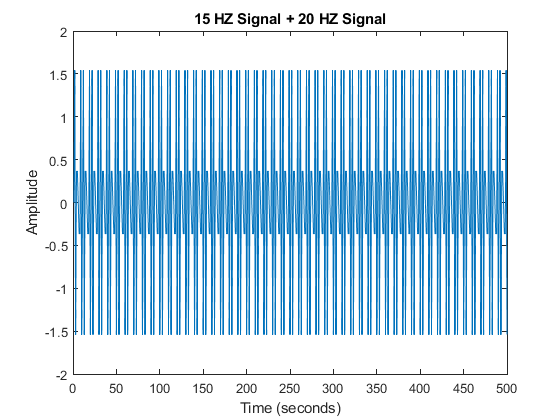

x = sin(2*pi*15*t2) + sin(2*pi*20*t2);
plot(x)
title("15 HZ Signal + 20 HZ Signal")
xlabel('Time (seconds)')
ylabel('Amplitude')

Now let's try to compute the Fourier transform and plot that.

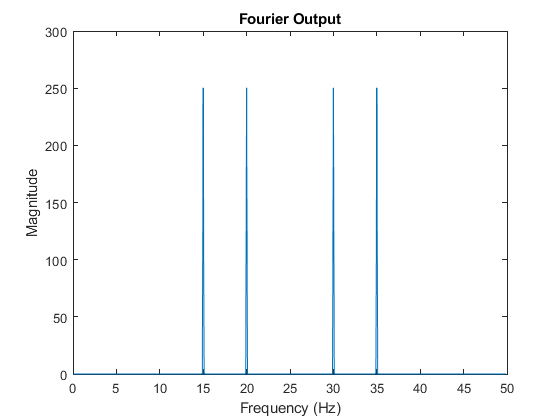

y = fft(x);   
fs = 1/Ts;
f = (0:length(y)-1)*fs/length(y);
plot(f,abs(y))
title("Fourier Output")
xlabel('Frequency (Hz)')
ylabel('Magnitude')

From this we can see that we were able to recover the fact that the signal is a combination of a 15 HZ signal and a 20 HZ one. We can immediately see how this might be useful in the case of analyzing our EEG data, where we know that the alpha waves live in a specific frequency (usually around 10 HZ).

## Analyze frequency spectrum

One of the first things we can do is analyze the frequency spectrum. ["pspectrum"](https://www.mathworks.com/help/signal/ref/pspectrum.html) is a function that allows us to analyze signals in the frequency and time-frequency domains by returning the power spectrum of the inputted data through the use of a discrete Fourier transform. This is useful as the power spectrum will provide us with a graphical representation of how much of a signal's power falls within a given frequency. 

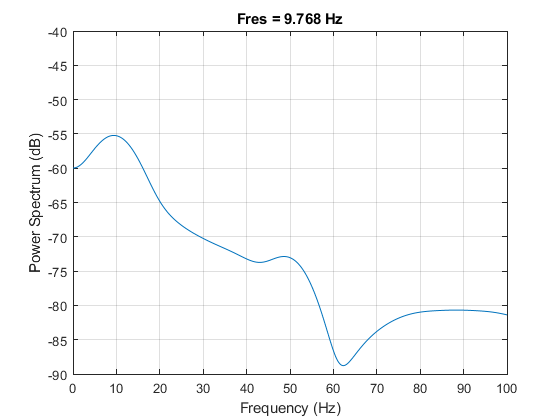

pspectrum(EEGsignalRaw,t,"FrequencyLimits",[0 100])
ylim([-90 -40])

## Create Scalogram

This next block of code performs a continuous wavelet transform. We do this so that we can easily see how the frequency content of a signal changes over time. Recall in the explanation of the Fourier transform that just doing the transform gives us information about what frequencies are present in the data, but we lose the time information. If we want to be able say at what time certain frequencies are occuring, we would need this method. 

The MathWorks documentation website also provides a short [explanation](https://www.mathworks.com/help/signal/ug/scalogram-computation-in-signal-analyzer.html) of the scalogram, stating: "The scalogram is the absolute value of the continuous wavelet transform (CWT) of a signal, plotted as a function of time and frequency.... the CWT is obtained by windowing the signal with a *wavelet* that is scaled and shifted in time." See documentation for the "cwt" function [here](https://www.mathworks.com/help/wavelet/ref/cwt.html). 

Now let's see what happens when we use this function on our EEG data. 

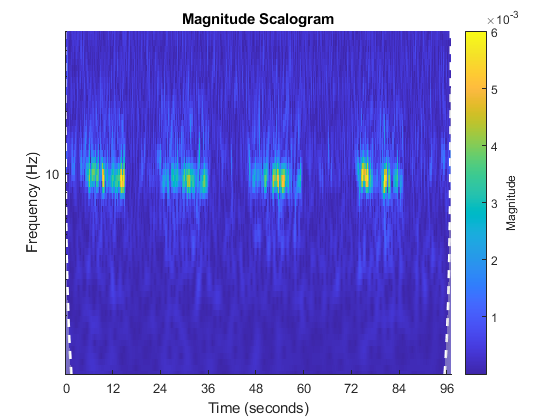

close all
cwt(tt(:,"EEGsignalRaw"),"FrequencyLimits",[1 50])
ax = gca;
ax.XTickLabel = num2str(60*str2double(ax.XTickLabel));
xlabel('Time (seconds)')

## Read annotation data

Alongside the actual signal data (the .wav file), we also generate a text file that indicates what time periods of the experiment correspond to when the patient has their eyes open or closed. This inforamation is stored in a .txt file that shares a name with the experimental data file, but with the added "-events.txt". In this blcok of code, we simply read in that file and load the corresponding data. 

events = readtable(dataset + "-events.txt",'VariableNamingRule',"preserve");
if dataset == "TimBrain_VisualCortex_BYB_Recording"
annotationPointsClose = events.Var3(strcmp(events.Var2,'closed,'));
annotationPointsOpen = events.Var3(strcmp(events.Var2,'open,'));
else
annotationPointsOpen = events.("Time (in s)")(strcmp(events.("# Marker ID"),'eyes open'));
annotationPointsClose = events.("Time (in s)")(strcmp(events.("# Marker ID"),'eyes closed relaxed'));
annotationPointsActive = events.("Time (in s)")(strcmp(events.("# Marker ID"),'eyes closed actively searching'));
end


## Add annotations to frequency scalogram

Now, we can use the loaded annotations to add more descriptive information to the frequency scalogram to indicate how the different states correspond to different areas of the scalogram. The annotations are added using the following formula: 


$$\frac{\textrm{ax}\ldotp \textrm{Position}\left(\textrm{end}-1\right)}{\textrm{ax}\ldotp \textrm{XLim}\left(\textrm{end}\right)}=\frac{x}{\textrm{annotationPoint}}$$


At this point, we can see that the alpha waves correspond to the eyes closed state, as that is when they are able to be detected most readily in our visualization.

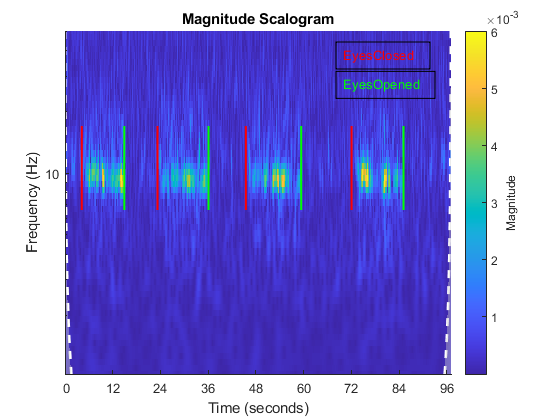

offset = ax.Position(end-1)/(ax.XLim(end)*60);

for i = 1:size(annotationPointsClose,1)
    a = annotation(gcf,"line",[ax.Position(1)+annotationPointsClose(i)*offset ax.Position(1)+annotationPointsClose(i)*offset],[0.5 0.7]);
    a.Color = 'red';
    a.LineWidth = 1.5;
    b = annotation(gcf,"line",[ax.Position(1)+annotationPointsOpen(i)*offset ax.Position(1)+annotationPointsOpen(i)*offset],[0.5 0.7]);
    b.Color = 'green';
    b.LineWidth = 1.5;
    if exist("annotationPointsActive",'var')
        c = annotation(gcf,"line",[ax.Position(1)+annotationPointsActive(i)*offset ax.Position(1)+annotationPointsActive(i)*offset],[0.5 0.7]);
        c.Color = 'white';
        c.LineWidth = 1.5;
    end
end
if exist("annotationPointsActive",'var')
    annotation('textbox',[.6 .6 .3 .3],'String','LightsOff','FitBoxToText','on','Color','red');
    annotation('textbox',[.6 .53 .3 .3],'String','LightsOn','FitBoxToText','on','Color','green');
    annotation('textbox',[.3 .6 .3 .3],'String','LightsOffActiveSearch','FitBoxToText','on','Color','white');
else
    annotation('textbox',[.6 .6 .3 .3],'String','EyesClosed','FitBoxToText','on','Color','red');
    annotation('textbox',[.6 .53 .3 .3],'String','EyesOpened','FitBoxToText','on','Color','green');
end

If it wasn't clear how to read the scalogram, the addition of the annotation data (as well as a comparison to the signal data replotted at the beginning of this script) should make things clearer. We now have the information for what frequencies occur by examining how warm the colors at the x,y coordinate corresponding to the time and frequency of interest. 

clear annotationPointsActive
clear EEGsignalRaw

© 2021 The MathWorks, Inc.